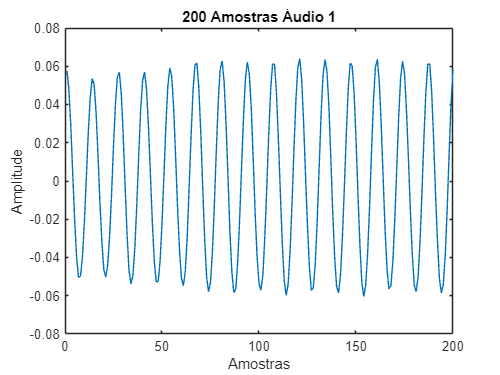

% Ler o arquivo WAV
[data1, samplerate1] = audioread('Assovio.wav');
[data2, samplerate2] = audioread('Testando123.wav');

% Exibir a taxa de amostragem e as dimensões dos dados
samplerate1;
size(data1);
samplerate2;
size(data2);


%plot(data1);
%title('Sinal de Áudio 1');
%xlabel('Amostras');
%ylabel('Amplitude');

%figure
%plot(data2);
%title('Sinal de Áudio 2');
%xlabel('Amostras');
%ylabel('Amplitude');


% Reproduzir o áudio
%sound(data1, samplerate);
%sound(data2, samplerate);

%1)
%a) Plote 200 amostras mais ou menos no centro de cada sinal em gráficos diferentes.
plot(data1(16001:16200));
title('200 Amostras Áudio 1');
xlabel('Amostras');
ylabel('Amplitude');

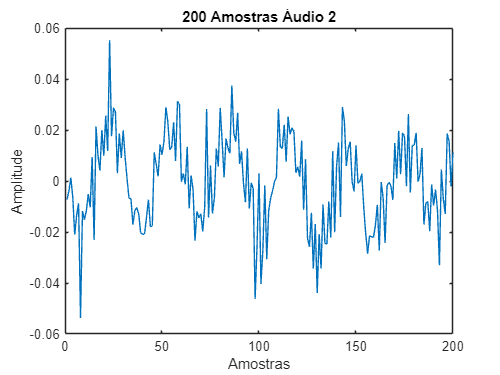

figure

plot(data2(16001:16200));
title('200 Amostras Áudio 2');
xlabel('Amostras');
ylabel('Amplitude');

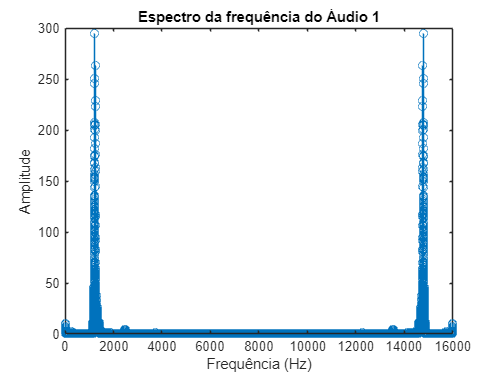

figure

%b) Plote a amplitude do espectro de frequências de cada sinal (valor absoluto da 
% fft modo stem) em gráficos separados.
% Calcular a FFT e o vetor de frequências
Y1 = fft(data1);
Y2 = fft(data2);
N1 = length(data1);
N2 = length(data2);
frequencies1 = (0:N1-1) * samplerate1 / N1;
frequencies2 = (0:N2-1) * samplerate2 / N2;

% Plotar o espectro de frequências para o primeiro sinal
stem(frequencies1, abs(Y1));
title('Espectro da frequência do Áudio 1');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

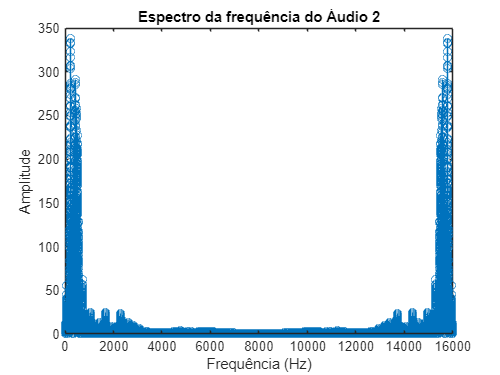

figure

% Plotar o espectro de frequências para o segundo sinal
stem(frequencies2, abs(Y2));
title('Espectro da frequência do Áudio 2');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

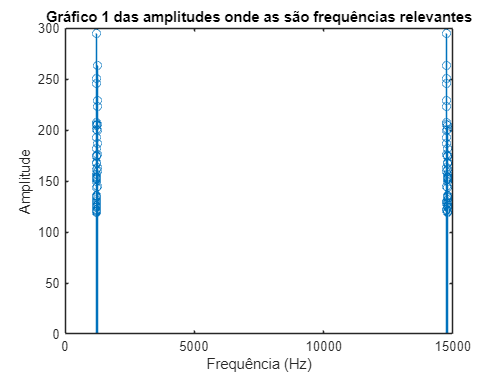

figure


%c) Plote a amplitude da região do espectro onde as frequências são mais 

% Calcular a amplitude e o limite de percentil
amplitude1 = abs(Y1);
amplitude2 = abs(Y2);
num_freq1 = 100;
limite2 = prctile(amplitude2, 95);

% Encontrar os índices das frequências mais relevantes e plotar o gráfico
[~, indices_maiores1] = maxk(amplitude1, num_freq1);
stem(frequencies1(indices_maiores1), amplitude1(indices_maiores1));
title('Gráfico 1 das amplitudes onde as são frequências relevantes');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

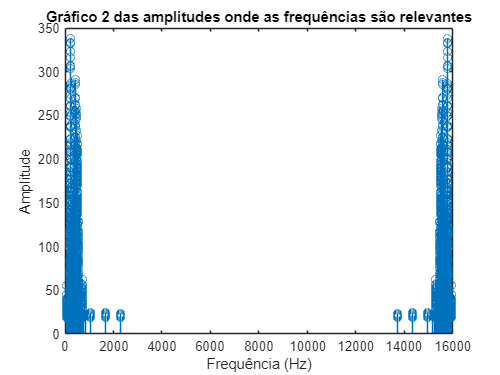


% Encontrar os índices das frequências mais relevantes e plotar o gráfico
indices_maiores2 = find(amplitude2 > limite2);
stem(frequencies2(indices_maiores2), amplitude2(indices_maiores2));
title('Gráfico 2 das amplitudes onde as frequências são relevantes');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

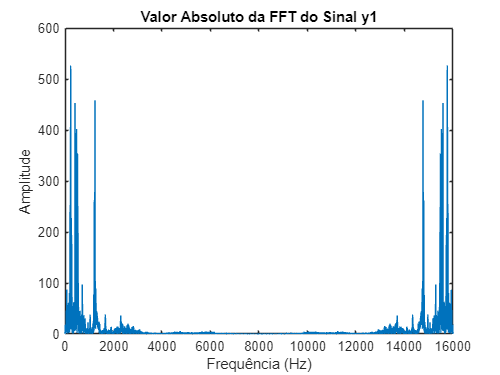

figure;


%d)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%2)
%a)Crie o sinal y1 com a soma dos dois áudios (se precisar aumente o audio menor zeros 
% no final, you diminua áudio maior removendo amostras). Gere um .wav e escute o sinal y1.

% Obter os tamanhos dos áudios
len1 = length(data1);
len2 = length(data2);

% Ajustar os tamanhos dos áudios
if len1 > len2
    data2 = [data2; zeros(len1 - len2, size(data2, 2))]; % Adicionar zeros ao final de data2
else
    data1 = [data1; zeros(len2 - len1, size(data1, 2))]; % Adicionar zeros ao final de data1
end

% Somar os áudios
y1 = data1 + data2;
% Normalizar o sinal resultante para evitar distorção
y1 = y1 / max(abs(y1), [], 'all');

% Salvar o sinal em um arquivo WAV
audiowrite('y1.wav', y1, samplerate1);
% Escutar o sinal resultante
%sound(y1, samplerate1);


%b)Calcule a fft do sinal y1, chamada Y1 e plote seu valor absoluto.

% Calcular a FFT do sinal y1
Y1 = fft(y1);

% Calcular o vetor de frequências correspondente à FFT
N1 = length(y1);
frequencies = (0:N1-1) * samplerate1 / N1;

% Plotar o valor absoluto da FFT do sinal y1
plot(frequencies, abs(Y1));
title('Valor Absoluto da FFT do Sinal y1');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

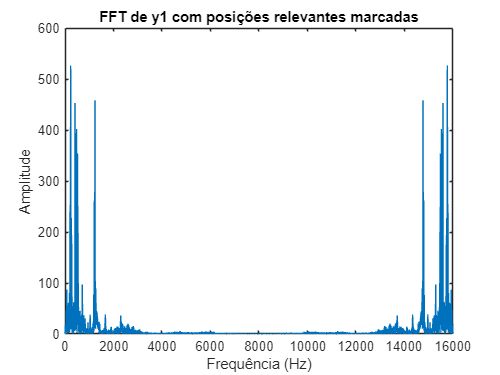

figure;

%c) Na fft (Y1) tente identificar quais as frequências do assovio (quais as posições 
% no array de saída correspondem ao assovio)

% Calcular as amplitudes
amplitude_y1 = abs(Y1);
amplitude_assovio = abs(Y_assovio);

% Definir um limite de amplitude para considerar frequências relevantes
limite_amplitude_assovio = max(amplitude_assovio) * 0.5;  % Exemplo: 50% do máximo de amplitude

% Identificar frequências relevantes no assovio
indices_assovio_relevantes = find(amplitude_assovio > limite_amplitude_assovio);

% Encontrar as posições no array de Y1 que correspondem às frequências relevantes do assovio
posicoes_relevantes_y1 = indices_assovio_relevantes;

% Calcular o vetor de frequências para o gráfico
N = length(y1);
frequencies_y1 = (0:N-1) * samplerate1 / N;

% Plotar o valor absoluto da FFT de y1
plot(frequencies_y1, amplitude_y1);
title('FFT de y1 com posições relevantes marcadas');
xlabel('Frequência (Hz)');
ylabel('Amplitude');

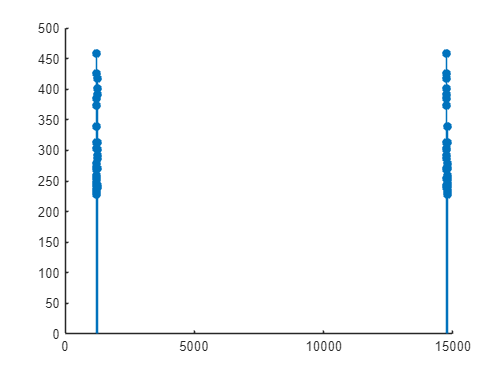

figure;
% Marcar as posições relevantes de y1 no gráfico
hold on;
stem(frequencies_y1(posicoes_relevantes_y1), amplitude_y1(posicoes_relevantes_y1), 'filled');
hold off;